# DL-SCH and PDSCH Processing Chain

Single slot, encoding/decoding.

## Simulation Parameters

SNRdB = 15;          % SNR in dB

## DL-SCH Configuration

Specify the DL-SCH parameters and create the DL-SCH encoder and decoder objects. In this example we do not consider HARQ, therefore the redundancy value (RV) is fixed.

% DL-SCH parameters
codeRate = 490/1024;
RV = 0; % redundancy value

% Create DL-SCH encoder object
encodeDLSCH = nrDLSCH;
encodeDLSCH.TargetCodeRate = codeRate;

% Create DLSCH decoder object
decodeDLSCH = nrDLSCHDecoder;
decodeDLSCH.TargetCodeRate = codeRate;
decodeDLSCH.LDPCDecodingAlgorithm = "Normalized min-sum";
decodeDLSCH.MaximumLDPCIterationCount = 6;

## Carrier Configuration

Set up a carrier configuration object. Here you can set up the numerology. We will use the default parameters.

carrier = nrCarrierConfig

carrier =   nrCarrierConfig with properties:

              NCellID: 1
    SubcarrierSpacing: 15
         CyclicPrefix: 'normal'
            NSizeGrid: 52
           NStartGrid: 0
                NSlot: 0
               NFrame: 0

   Read-only properties:
       SymbolsPerSlot: 14
     SlotsPerSubframe: 1
        SlotsPerFrame: 10


Set the desired slot number.

carrier.NSlot = 0;

## PDSCH and DM-RS Configuration

Set up a PDSCH configuration object. We will use 16QAM modulation and full band allocation. Other time allocation parameters and DM-RS settings can be specified in this object.

pdsch = nrPDSCHConfig;
pdsch.Modulation = "16QAM";
pdsch.PRBSet = 0:carrier.NSizeGrid-1;     % assume full band allocation

Display the PDSCH and PDSCH DM-RS parameters.

pdsch

pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


pdsch.DMRS

ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 1
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


## Channel Configuration

nTxAnts = 1;
nRxAnts = 1;
channel = nrTDLChannel; % TDL channel object
channel.DelayProfile = 'TDL-A';
channel.MaximumDopplerShift = 5;
channel.NormalizeChannelOutputs = true;
channel.NormalizePathGains = true; % normalize to make sure all path gains = 0dB
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
channel.MIMOCorrelation = 'Low';

Set the channel sampling rate.

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;

## Calculate Transport Block Size

% Generate PDSCH indices info, this is used to calculate the transport
% block size
[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

% Number of codewords
numCw = 1;

% Calculate transport block sizes
Xoh_PDSCH = 0;
trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschInfo.NREPerPRB,codeRate,Xoh_PDSCH);

## DL-SCH Encoding

% Generate new transport block
trBlk = randi([0 1],trBlkSizes(numCw),1);
setTransportBlock(encodeDLSCH,trBlk,numCw-1);

% Encode the DL-SCH transport blocks
codedTrBlock = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers,pdschInfo.G,RV);

## PDSCH Modulation

Generate PDSCH symbols

pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlock);

## PDSCH DM-RS Generation

Generate DM-RS symbols and indices.

dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);

## Mapping to Resource Grid

Generate an empty resource grid. This grid represents a slot.

pdschGrid = nrResourceGrid(carrier);

Map the PDSCH symbols to the grid and display the resource grid. Note the gap left for the DM-RS.

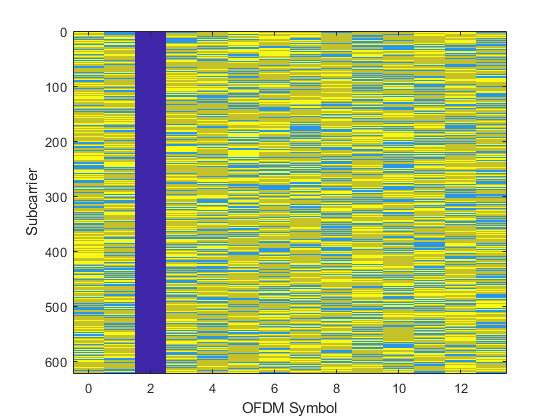

pdschGrid(pdschIndices) = pdschSymbols;
figure;imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid));xlabel('OFDM Symbol');ylabel('Subcarrier')

Map the DM-RS symbols to the grid.

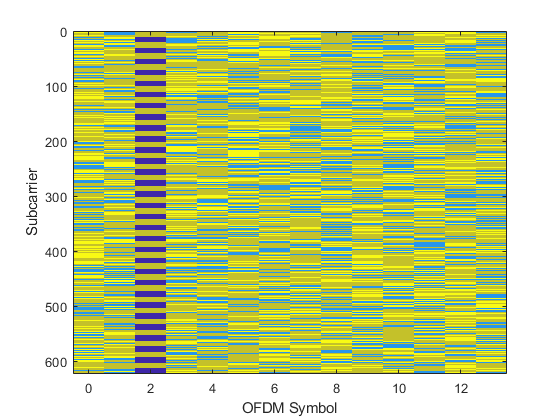

pdschGrid(dmrsIndices) = dmrsSymbols;
imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid));xlabel('OFDM Symbol');ylabel('Subcarrier')

## OFDM Modulation

Perform OFDM modulation of the resource grid.

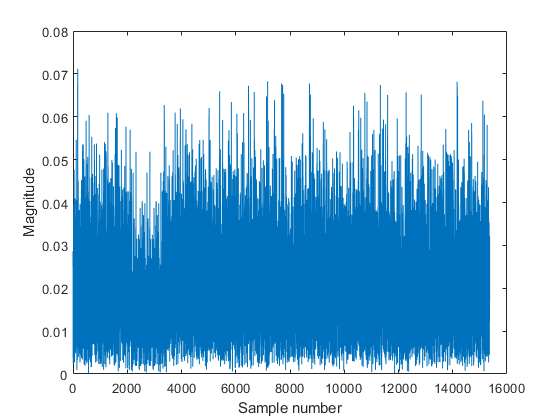

[txWaveform,waveformInfo] = nrOFDMModulate(carrier,pdschGrid);
figure;plot(abs(txWaveform));xlabel('Sample number');ylabel('Magnitude')

## Channel

% Add AWGN 
rxWaveform = channel(txWaveform);
noise = generateAWGN(SNRdB,nRxAnts,waveformInfo.Nfft,size(rxWaveform));
rxWaveform = rxWaveform + noise;

## OFDM Demodulation

rxGrid = nrOFDMDemodulate(carrier,rxWaveform);

## Channel Estimation

[estChGrid,noiseEst] = nrChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);

Plot the channel estimate between the first transmit and the first receive antenna.

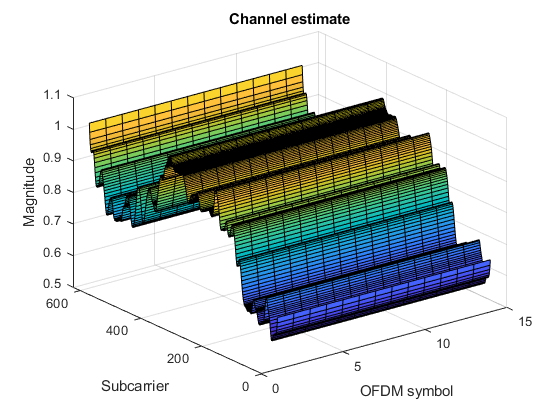

figure;surf(abs(estChGrid(:,:,1,1)));
title('Channel estimate')
xlabel('OFDM symbol');ylabel("Subcarrier");zlabel("Magnitude")


% Equalization and PDSCH decoding.
[pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChGrid);

## Equalization

[pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

Create a constellation diagram.

constPlot = comm.ConstellationDiagram;

Enable measurements to check the EVM. Specify the reference constellation points

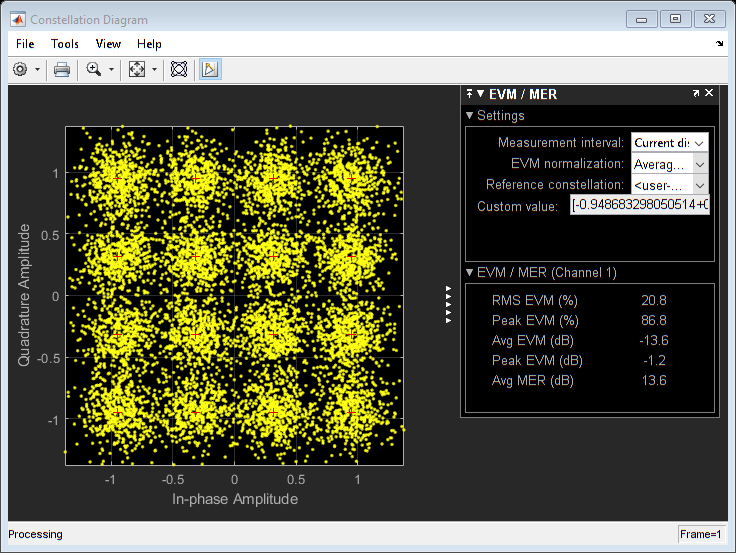

constPlot.EnableMeasurements = 1;
constPlot.ReferenceConstellation = pdschSymbols;
constPlot(pdschEq)

## PDSCH Decoding

[dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);

Scale LLRs by CSI

% Scale LLRs by CSI
csi = nrLayerDemap(csi); % CSI layer demapping
for cwIdx = 1:pdsch.NumCodewords
    Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % bits per symbol
    csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);   % expand by each bit per symbol
    dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % scale
end

## DL-SCH Decoding

% Decode the DL-SCH transport channel
decodeDLSCH.TransportBlockLength = trBlkSizes;
[decbits,blkerr] = decodeDLSCH(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,RV);
reset(decodeDLSCH); % reset soft buffers
if ~blkerr
    disp("No errors")
else
    disp("Errors detected")
end

No errors


## Local functions

function noise = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
% Generate AWGN for a given value of SNR in dB (SNRDB). This is the
% receiver SNR per resource element and antenna assuming the channel does
% not affect the power of the signal. NRXANTS is the number of receive
% antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
% is the size of the receive waveform used to calculate the size of the
% noise matrix.

    % Normalize noise power to take account of sampling rate, which is
    % a function of the IFFT size used in OFDM modulation. The SNR
    % is defined per RE for each receive antenna (TS 38.101-4).
    SNR = 10^(SNRdB/20); % Calculate linear noise gain
    N0 = 1/(sqrt(2.0*nRxAnts*double(Nfft))*SNR);
    noise = N0*complex(randn(sizeRxWaveform),randn(sizeRxWaveform));
end